# Dimensionality Reduction by Pre-Trained SA-LSUN

## Preparation

clc, clear
close all

## Loading input image

Datasetfolder ='./Experience2/Dataset';
files = dir(fullfile(Datasetfolder,'*.mat'));
data = load(fullfile(Datasetfolder,files(1).name));
u = single(data.u);

if canUseGPU
    disp("Use GPU")
    u = gpuArray(u);
end

Use GPU


[szy,szx,szt] = size(u);

### Load trained parameter

pass = "./Experience1/Result/SA_LSUN/K_2/";
load(pass+"parameter_ini.mat");
load(pass+"parameter_hor.mat");
load(pass+"parameter_ver.mat");

## Setting

Setting of LSUN

blksz = [4, 4];             % Block Size
p = prod(blksz);            % Number of Channel
nCoefs = 2;                 % Number of Coefficient
ovlp = [3,3];               % Number of Overlap(Fixed)
neibor = [3,3];             % Number of input blocks for the parameter estimator
nBlks = [szy,szx]./blksz;   % Number of Block
N = prod(nBlks);            % All Blocks

% Mask
coefMask = reshape([ones(nCoefs,1); zeros(p-nCoefs,1)],2,[]).';
coefMask = coefMask(:);

## Approximation by LSUN-base linear autoencoder

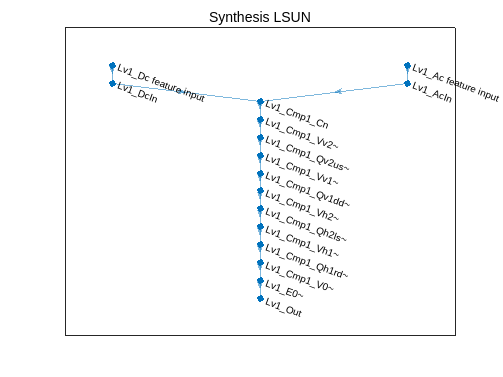

% analysis LSUN
X_DCT = DCT_2D(u, blksz(1), blksz(2));

angles0 = lsunAngleEstimate(X_DCT,w_ini,b_ini, ...
    g_ini,beta_ini,neibor,"Initial");
X_R0 = Rot_initial(X_DCT,angles0);

X_shift_R = atomext_(X_R0,'Right','Difference');
anglesUh1 = lsunAngleEstimate(X_shift_R, w_hor(:,1),b_hor(:,1), ...
    g_hor(:,1),beta_hor(:,1),neibor,"Inter");
X_R1 = Rot_inter(X_shift_R,anglesUh1,-1);

X_shift_L = atomext_(X_R1,'Left','Sum');
anglesUh2 = lsunAngleEstimate(X_shift_L, w_hor(:,2),b_hor(:,2), ...
    g_hor(:,2),beta_hor(:,2),neibor,"Inter");
X_R2 = Rot_inter(X_shift_L,anglesUh2,1);

X_shift_D = atomext_(X_R2,'Down','Difference');
anglesUv1 = lsunAngleEstimate(X_shift_D, w_ver(:,1),b_ver(:,1), ...
    g_ver(:,1),beta_ver(:,1),neibor,"Inter");
X_R3 = Rot_inter(X_shift_D,anglesUv1,-1);

X_shift_U = atomext_(X_R3,'Up','Sum');
anglesUv2 = lsunAngleEstimate(X_shift_U, w_ver(:,2),b_ver(:,2), ...
    g_ver(:,2),beta_ver(:,2),neibor,"Inter");
dlX = Rot_inter(X_shift_U,anglesUv2,1);

dlX = coefMask(:).*dlX;

Loss = sum(u.^2,"all")/szt- sum(dlX.^2,"all")/szt;

% Use the existing synthesis layer structure
import tansacnet.lsun.*
lsunlgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',blksz,...
    'OverlappingFactor',[3 3],...
    'NumberOfVanishingMoments','true',...
    'Mode','Synthesizer');

figure
plot(lsunlgraph)
title('Synthesis LSUN')

predict

% Creating Networks and Copying Parameters
net = dlnetwork(lsunlgraph);
u = gather(u);
u_reconstruct = zeros(szy,szx,szt,'like',u);

dlx = cell(1,2);

for iSample = 1:szt
    dlx{1} = dlarray(permute(dlX(2:p,:,:,iSample),[2 3 1 4]),'SSCB');
    dlx{2} = dlarray(permute(dlX(1,:,:,iSample),[2 3 1 4]),'SSCB');
    net.Learnables.Value{1} = dlarray(anglesUv2(:,:,iSample));
    net.Learnables.Value{2} = dlarray(anglesUv1(:,:,iSample));
    net.Learnables.Value{3} = dlarray(anglesUh2(:,:,iSample));
    net.Learnables.Value{4} = dlarray(anglesUh1(:,:,iSample));
    net.Learnables.Value{5} = dlarray(angles0(:,:,iSample));
    u_reconstruct(:,:,iSample) = net.predict(dlx{:});

end

### Performance Evaluation and Save Results

mse = mean((u - u_reconstruct).^2,'all')

mse = single
1.3111e-05

mae = mean(abs(u - u_reconstruct),'all')

mae = single
0.0021


pass = "./Experience2/Result/SA_LSUN/UseLearnedPara/";
%% Save WorkSpace
writematrix(mse,pass + "mse.txt");
writematrix(mae,pass + "mae.txt");
writematrix(Loss,pass + "loss.txt");

save(pass + "u_reconstruct.mat","u_reconstruct");

## Layer Construct function

Parameter Estimation Network (Fully Connected Layer + GELU Layer)

function angles = lsunAngleEstimate(X,w,b,g,beta,overlap,select)

p = size(X,1);
nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
part = size(g,1);

w1 = cat(3, w{1:2:end-2});
b1 = cat(3, b{1:2:end-2});
w2 = cat(3, w{2:2:end-1});
b2 = cat(3, b{2:2:end-1});
g = cat(3, g{:});
beta = cat(3, beta{:});

w_o = w{end};
bias_o = b{end};

if select == "Initial"
    angles = zeros(p*(p-2)/4,nrows*ncols,nSamples,"like",X);
    
    X_ = [];
    for vertial = fix(overlap(1)/2):-1:-1*fix(overlap(1)/2)
        for horizon = fix(overlap(2)/2):-1:-1*fix(overlap(2)/2)
            X_neighbor = circshift(X,[0,vertial,horizon,0]);
            X_neighbor = X_neighbor(2:p,:,:,:);
            X_ = cat(1,X_,X_neighbor);
        end
    end
    X_ = reshape(X_,(p-1)*overlap(1)*overlap(2),nrows*ncols,nSamples);
else
    angles = zeros(p*(p-2)/8,nrows*ncols,nSamples,'like',X);

    X_ = [];
    for vertial = fix(overlap(1)/2):-1:-1*fix(overlap(1)/2)
        for horizon = fix(overlap(2)/2):-1:-1*fix(overlap(2)/2)
            X_neighbor = circshift(X,[0,vertial,horizon,0]);
            X_neighbor = X_neighbor(p/2+1:p,:,:,:);
            X_ = cat(1,X_,X_neighbor);
        end
    end
    X_ = reshape(X_,p/2*overlap(1)*overlap(2),nrows*ncols,nSamples);
end

% Standardization of Input
mu = mean(X_, 2);
sigma = std(X_, 0, 2) + 1e-8;
X_ = (X_ - mu) ./ sigma;

for iSample = 1:nSamples
    Y = X_(:,:,iSample);

    for ipart = 1:part
        % Layer Normalization
        [n_ln,~,~] = LayerNormalization(Y,g(:,:,ipart),beta(:,:,ipart));
    
        % Fully Connected Layer
        n_z1 =  FullyConnected(n_ln,w1(:,:,ipart),b1(:,:,ipart));
    
        % GeLU Layer
        n_a = gelu(n_z1);
        
        % Fully Connected Layer
        n_z2 = FullyConnected(n_a,w2(:,:,ipart),b2(:,:,ipart));

        residual = n_z2;        
        Y = Y + residual;
    end
    % Fully Connected Layer
    iAngles =  FullyConnected(Y,w_o,bias_o);
    
    if select == "Initial"
        NoDCleak = zeros(p/2-1,nrows*ncols,'like',iAngles);
        iAngles = cat(1,NoDCleak,iAngles);
        angles(:,:,iSample) = iAngles;
    else
        angles(:,:,iSample) = iAngles;
    end
end

end

**Function of Constructing Analysis LSUN**

2-D Block DCT

function X_DCT = DCT_2D(X, decV, decH)
nDec = decV*decH;

nRows = size(X,1)/decV;
nCols = size(X,2)/decH;
nSamples = size(X,3);

Cv_ = dctmtx(decV);
Ch_ = dctmtx(decH);
Cv_ = [ Cv_(1:2:end,:) ; Cv_(2:2:end,:) ];
Ch_ = [ Ch_(1:2:end,:) ; Ch_(2:2:end,:) ];
%
Cve = Cv_(1:ceil(decV/2),:);
Cvo = Cv_(ceil(decV/2)+1:end,:);
Che = Ch_(1:ceil(decH/2),:);
Cho = Ch_(ceil(decH/2)+1:end,:);
Cee = kron(Che,Cve);
Coo = kron(Cho,Cvo);
Coe = kron(Che,Cvo);
Ceo = kron(Cho,Cve);
Cvh = [Cee; Coo; Coe; Ceo];
arrayX = permute(reshape(X, decV,nRows,decH,nCols,nSamples),[1 3 2 4 5]);
if isgpuarray(X)
    X_DCT = pagefun(@mtimes,Cvh,...
        reshape(arrayX,nDec,nRows,nCols,nSamples));
else
    X_DCT = reshape(Cvh*reshape(arrayX,nDec,[]),nDec,nRows,nCols,nSamples);
end
end

Initial Rotation

function X_Rot_ini = Rot_initial(X,angles)
nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
ps = size(X,1)/2;
pa = ps;

mus = ones(ps+pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles);
muW = mus(1:ps,:,:);        % Revised
muU = mus(ps+1:end,:,:);        % Revised

angles(1:ps-1,:,:) = zeros(ps-1,nrows*ncols,nSamples,'like',angles);       % Revised

anglesW = angles(1:size(angles,1)/2,:,:);       % Revised
anglesU = angles(size(angles,1)/2+1:end,:,:);   % Revised

W0_ = fcn_orthmtxgen(anglesW,muW);
U0_ = fcn_orthmtxgen(anglesU,muU);

Y = reshape(X,ps+pa,nrows*ncols,nSamples);
Zs = zeros(ps,nrows*ncols,nSamples,'like',Y);
Za = zeros(pa,nrows*ncols,nSamples,'like',Y);

for iSample = 1:nSamples
    if isgpuarray(X)
        Ys_iSample = permute(Y(1:ps,:,iSample),[1 4 2 3]);
        Ya_iSample = permute(Y(ps+1:end,:,iSample),[1 4 2 3]);
        Zs_iSample = pagefun(@mtimes,W0_(:,:,:,iSample),Ys_iSample);        % Revised
        Za_iSample = pagefun(@mtimes,U0_(:,:,:,iSample),Ya_iSample);        % Revised
        Zs(:,:,iSample) = ipermute(Zs_iSample,[1 4 2 3]);
        Za(:,:,iSample) = ipermute(Za_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Zs(:,iblk,iSample) = W0_(:,1:ps,iblk,iSample)*Y(1:ps,iblk,iSample);
            Za(:,iblk,iSample) = U0_(:,1:pa,iblk,iSample)*Y(ps+1:end,iblk,iSample);
        end
    end
end

X_Rot_ini = reshape([Zs;Za],ps+pa,nrows,ncols,nSamples);

end

Shift & Butterfly Operation

function X_shift = atomext_(X,dir,target)
ps = size(X,1)/2;
pa = ps;

% Block Butterfly Operation
Xs = X(1:ps,:,:,:);
Xa = X(ps+1:ps+pa,:,:,:);
Ys =  bsxfun(@plus,Xs,Xa);
Ya =  bsxfun(@minus,Xs,Xa);

% Shift operation
if strcmp(dir,'Right')
    shift = [ 0 0 1 0];
elseif strcmp(dir,'Left')
    shift = [ 0 0 -1 0];
elseif strcmp(dir,'Down')
    shift = [ 0 1 0 0];
elseif strcmp(dir,'Up')
    shift = [ 0 -1 0 0];
else
    throw(MException('NsoltLayer:InvalidDirection',...
        '%s : Direction should be either of Right, Left, Down or Up',...
        layer.Direction))
end
if strcmp(target,'Difference')
    Ya = circshift(Ya,shift);
elseif strcmp(target,'Sum')
    Ys = circshift(Ys,shift);
else
    throw(MException('NsoltLayer:InvalidTargetChannels',...
        '%s : TaregetChannels should be either of Sum or Difference',...
        layer.TargetChannels))
end

% Block Butterfly Operation
Y =  cat(1,bsxfun(@plus,Ys,Ya),bsxfun(@minus,Ys,Ya));

X_shift = 0.5*Y;
end

Intermadiate Rotation

function X_Rot_int = Rot_inter(X,angles,Mus)

nrows = size(X,2);
ncols = size(X,3);
nSamples = size(X,4);
ps = size(X,1)/2;
pa = ps;

mus = Mus*ones(pa,nrows*ncols,nSamples);     % Revised
mus = cast(mus,'like',angles);
Un_ = fcn_orthmtxgen(angles,mus);

Y = X;
Ya = reshape(Y(ps+1:ps+pa,:,:,:),pa,nrows*ncols,nSamples);
A_ = Un_;

Za = zeros(pa,nrows*ncols,nSamples,'like',Y);
for iSample = 1:nSamples
    if isgpuarray(X)
        Ya_iSample = permute(Ya(:,:,iSample),[1 4 2 3]);
        Za_iSample = pagefun(@mtimes,A_(:,:,:,iSample),Ya_iSample);
        Za(:,:,iSample) = ipermute(Za_iSample,[1 4 2 3]);
    else
        for iblk = 1:(nrows*ncols)
            Za(:,iblk,iSample) = A_(:,:,iblk,iSample)*Ya(:,iblk,iSample);
        end
    end
end
Y(ps+1:ps+pa,:,:,:) = reshape(Za,pa,nrows,ncols,nSamples);
X_Rot_int = Y;
end

Generation of Rotation Matrices

function matrix = fcn_orthmtxgen(angles,mus)                % Revised
useGpu = isgpuarray(angles);
nDim_ = (1+sqrt(1+8*size(angles,1)))/2;
nMatrices_ = size(angles,2);
nSamples = size(angles,3);      % Revised
matrix = repmat(eye(nDim_,'like',angles),[1 1 nMatrices_ nSamples]);        % Revised
if useGpu
    if ~isempty(angles)
        %for iMtx = 1:nMatrices_
        iAng = uint32(1);
        for iTop=1:nDim_-1
            vt = matrix(iTop,:,:,:);      % Revised
            for iBtm=iTop+1:nDim_
                angle = permute(angles(iAng,:,:),[1 4 2 3]);      % Revised
                %
                c = cos(angle);
                s = sin(angle);
                vb = matrix(iBtm,:,:,:);        % Revised
                %
                u = pagefun(@times,s,bsxfun(@plus,vt,vb));
                vt = bsxfun(@minus,pagefun(@times,bsxfun(@plus,c,s),vt),u);
                matrix(iBtm,:,:,:) = bsxfun(@plus,pagefun(@times,bsxfun(@minus,c,s),vb),u);     % Revised
                %u  = arrayfun(@(s,vt,vb) s.*(vt+vb),s,vt,vb);
                %vt = arrayfun(@(c,s,vt,u) (c+s).*vt-u,c,s,vt,u);
                %matrix(iBtm,:,:) = arrayfun(@(c,s,vb,u) (c-s).*vb+u,c,s,vb,u);
                %
                iAng = iAng + 1;
            end
            matrix(iTop,:,:,:) = vt;        % Revised
        end
        %end
    end
    if isvector(mus) || isscalar(mus)
        matrix = pagefun(@times,permute(mus(:),[1 4 3 2]),matrix);      % Revised
    else
        matrix = pagefun(@times,permute(mus,[1 4 2 3]),matrix);     % Revised
    end
else
    if ~isempty(angles)
        for iSample = 1:nSamples        % Revised
            for iMtx = 1:nMatrices_
                iAng = uint32(1);
                for iTop=1:nDim_-1
                    vt = matrix(iTop,:,iMtx,iSample);       % Revised
                    for iBtm=iTop+1:nDim_
                        angle = angles(iAng,iMtx,iSample);      % Revised
                        if angle ~= 0
                            c = cos(angle);
                            s = sin(angle);
                            vb = matrix(iBtm,:,iMtx,iSample);       % Revised
                            
                            u  = s.*(vt+vb);
                            vt = (c+s).*vt-u;
                            matrix(iBtm,:,iMtx,iSample) = (c-s).*vb+u;      % Revised
                            
                        end
                        %
                        iAng = iAng + 1;
                    end
                    matrix(iTop,:,iMtx,iSample) = vt;       % Revised
                end
            end
        end
    end
    for iSample = 1:nSamples        % Revised
        for iMtx = 1:nMatrices_
            if isvector(mus) || isscalar(mus)
                matrix(:,:,iMtx,iSample) = mus(:).*matrix(:,:,iMtx,iSample);        % Revised
            else
                matrix(:,:,iMtx,iSample) = mus(:,iMtx,iSample).*matrix(:,:,iMtx,iSample);       % Revised
            end
        end
    end
end
end

Layer Normalization

function [y,varx,xhat] = LayerNormalization(x,g,beta)
    mu   = mean(x,1);
    varx = mean((x-mu).^2,1);
    xhat = (x-mu) ./ sqrt(varx + 1e-5);
    y = g .* xhat + beta;
end

Fully Connected

function y = FullyConnected(x,W,b)
    y = W*x + b;
end

GELU Function

function y = gelu(x)
    y = 0.5 .* x .* (1 + tanh(sqrt(2/pi) .* (x + 0.044715 .* x.^3)));
end